# Using Quaternion sentences 

## Quaternion instances: rotation about z [0 0 1] a small angle

theta=0.1

theta = 0.1000


q1 = UnitQuaternion(rotz(0.1))

 
q1 = 
 
0.99875 < 0, 0, 0.049979 >
 



q2 = UnitQuaternion( rpy2tr(0, 0, theta))

 
q2 = 
 
0.99875 < 0, 0, 0.049979 >
 



q3 = UnitQuaternion.rpy(0,0,theta)

 
q3 = 
 
0.99875 < 0, 0, 0.049979 >
 



q4 = UnitQuaternion.angvec((theta), [0 0 1])

 
q4 = 
 
0.99875 < 0, 0, 0.049979 >
 



e4=cos(theta/2)

e4 = 0.9988

e1=0

e1 = 0

e2=0

e2 = 0

e3=1*sin(theta/2)

e3 = 0.0500

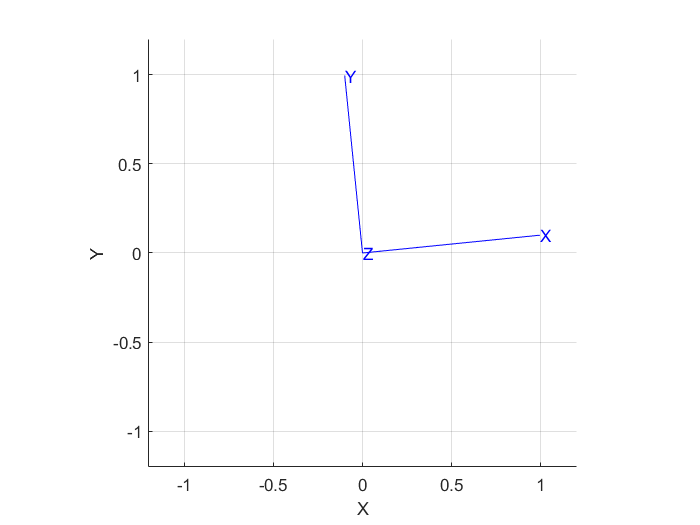


q3.plot


w=q4*[0 0 1]' % rotating unitary vector [0 0 1] does not change, The RTB also implement the 

w =      0
     0
     1


              % matrix multiplication form
              

#### Consider a rotation 2*pi/3 in R3 about the vector u =  [ 1 1 1 ]

theta= 2*pi/3

theta = 2.0944

u=[1 1 1]

u =      1     1     1


q5=UnitQuaternion.angvec((theta), [u])

 
q5 = 
 
0.5 < 0.5, 0.5, 0.5 >
 


q5.R

ans =          0   -0.0000    1.0000
    1.0000         0   -0.0000
   -0.0000    1.0000         0


W=q5*[0 0 1]'

W =     1.0000
   -0.0000
    0.0000


Displaying

A=eye(3) % The reference frame

A =      1     0     0
     0     1     0
     0     0     1


    trplot(A, ... %We plot the reference frame U with all the options
        'frame', 'A', ... 
        'color', 'g',...
        'arrow',...
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'axis',[-1 1 -1 1 -1 1],...
        'view',[-60,-36],...
        'width', 1.2)
    hold on
mArrow3([0 0 0],u,'color','blue','stemWidth',0.02,'facealpha',0.5)

ans =   Patch - 属性:

    FaceColor: [0 0 1]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [302×251 double]
     Vertices: [354×3 double]

  显示 所有属性


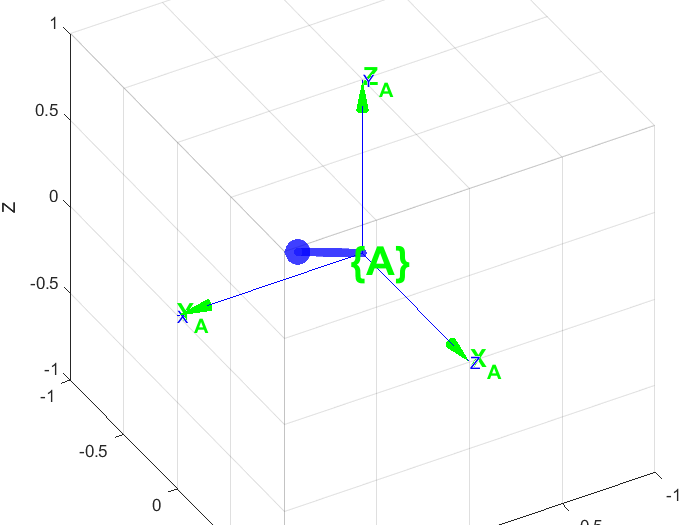

tranimate (A,q5.R,40)

Generalitation: Given two Reference Frames $X^B$ and  $X^A$ find the Quaternion such that rotating $X^B$ yield $X^A$.

Cue: $X^A$=$QX^B$

XB=eul2tr(0.1,0.2,0.3)

XB =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


XA=eul2tr(0.3,0.6,0.4)

XA =     0.6112   -0.5792    0.5394         0
    0.5967    0.7849    0.1669         0
   -0.5201    0.2199    0.8253         0
         0         0         0    1.0000


H1=trplot(XB, ... %We plot the reference frame Xb
    'frame', 'XB', ... 
    'color', 'b',...
    'arrow',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[130,30],...
    'width', 1.2)

H1 =   Transform with properties:

    Children: [10×1 Graphics]
     Visible: 'on'
     HitTest: 'on'
      Matrix: [4×4 double]

  Show all properties


hold on
H2=trplot(XA, ... %We plot the reference frame Xw 
    'frame', 'XA', ... 
    'color', 'r',...
    'arrow',...
    'text_opts', {'FontSize', 12, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[130,30],...
    'width', 1.2)

H2 =   Transform with properties:

    Children: [10×1 Graphics]
     Visible: 'on'
     HitTest: 'on'
      Matrix: [4×4 double]

  Show all properties


tranimate (XB,XA,40)
R_B_A=t2r(XA)'*t2r(XB)

R_B_A =     0.8813    0.2850   -0.3771
   -0.2601    0.9585    0.1166
    0.3946   -0.0047    0.9188


[ang vec]=tr2angvec(R_B_A)

ang = 0.4964

vec =    -0.1273   -0.8102   -0.5722


h = mArrow3([0 0 0],vec,'color','red','stemWidth',0.02,'facealpha',0.5)

h =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [302×251 double]
     Vertices: [354×3 double]

  Show all properties


Q=UnitQuaternion(R_B_A) % We get the quaternion of R_b_w

 
Q = 
 
0.96936 < -0.031263, -0.19902, -0.14058 >
 


Q.R

ans =     0.8813    0.2850   -0.3771
   -0.2601    0.9585    0.1166
    0.3946   -0.0047    0.9188


XB

XB =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


n_XA=Q*t2r(XB)' % we multiply by XB' to do it in WR {B}

n_XA =     0.6112    0.5967   -0.5201
   -0.5792    0.7849    0.2199
    0.5394    0.1669    0.8253


XA' % How 

ans =     0.6112    0.5967   -0.5201         0
   -0.5792    0.7849    0.2199         0
    0.5394    0.1669    0.8253         0
         0         0         0    1.0000


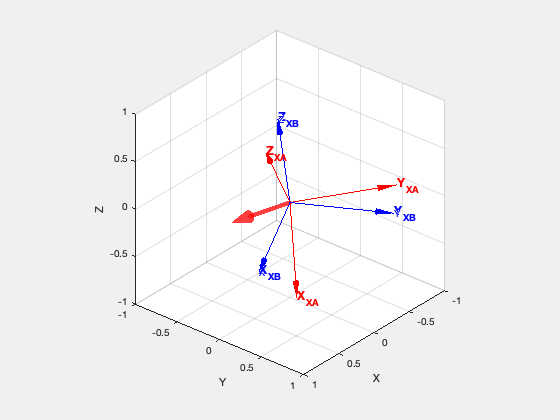


tranimate(XB,n_XA,20)


n_XA=t2r(XB)*R_B_A'

n_XA =     0.6112   -0.5792    0.5394
    0.5967    0.7849    0.1669
   -0.5201    0.2199    0.8253


XA

XA =     0.6112   -0.5792    0.5394         0
    0.5967    0.7849    0.1669         0
   -0.5201    0.2199    0.8253         0
         0         0         0    1.0000
